# initial values and commands

F = @(xy,a, b) [a-xy(1)^2+b*xy(2);xy(1)] % Duffling Map

F =     @(xy,a,b)[a-xy(1)^2+b*xy(2);xy(1)]


F_Jacobian = @(xy,a, b) [-2*xy(1) b;1 0] % Duffling Jacobian

F_Jacobian =     @(xy,a,b)[-2*xy(1),b;1,0]


max_time = 500; % How long to run (= number of samples to average)
rho_range = 0.1:0.01:1.6; % Range over parameter 1: (a for Duffling Map)
gammar = 0.3; % Fix parameter 2 (b for Duffling Map)
% Initial values for x and y
x0 = 0.3;
y0 = 0.01;
% Calculate the maximum Lyapunov exponents
[max_lyapunovs,rho_max_lyapunovs, max_max_lyapunovs] = lyapunov2d(F, F_Jacobian, max_time, rho_range,...
gammar, x0, y0);

The largest max_laypunovs is .4.252439e-01
Rho is 1.420000e+00 with the largest max_laypunovs.


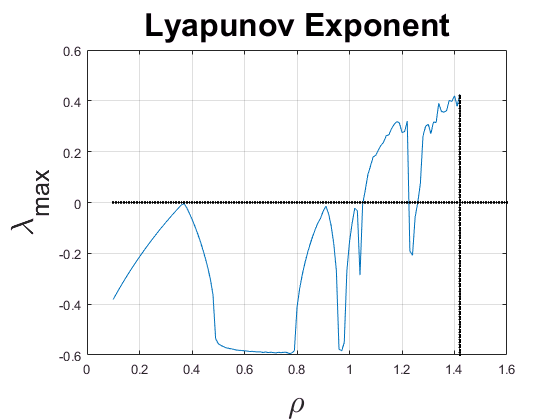

% Make a plot of the maximum exponents with a line at 0
plot(rho_range,max_lyapunovs, rho_range, 0, 'k.')
xlabel('\rho', 'FontSize', 24);
ylabel('\lambda_{max}', 'FontSize', 24);
title('Lyapunov Exponent','FontSize', 24);
grid on;